# **Steering Linkage Simulation**

This script allows changing of steering linkage parameters and reflects these changes in visuals and plots.

At the moment everything is set up assuming a 2D linkage.

To view everything simultaneously, select 'Hide Code', and zoom out using `ctrl + `[`-`]

%% Base Values %%
clear; format shortG;

% Constants
wheelbase = 2000;
trackwidth = 1100;
rnp_base_length = inch(11.25);
rack_max_travel = inch(4+5/8);
rnp_ratio = 12;

% Flexible Parameters
extension_rod_length = 70;
tie_rod_length = 280;
steering_arm_Ivec = [20 150];  % x-inset, y-inset (from kingpin)
kingpin2contact = 50;  % to centre of contact patch (scrub radius kinda)

% *the above simply for a vertical kingpin with no offset

%% Checks and Basic Calculations %%
% Calculated Constants
rnp_length = rnp_base_length + 2*extension_rod_length;
tie_rod_Ivec(1) = 0.5*trackwidth - kingpin2contact - steering_arm_Ivec(1) - 0.5*rnp_length;
tie_rod_Ivec(2) = sqrt(tie_rod_length^2 - tie_rod_Ivec(1)^2);
setback = steering_arm_Ivec(2) + tie_rod_Ivec(2);
kingpin_pos = [0.5*trackwidth - kingpin2contact, wheelbase];
kingpin_posL = [-0.5*trackwidth + kingpin2contact, wheelbase];

% Verify geometry
foo = rnp_length + 2*steering_arm_Ivec(1) + 2*kingpin2contact;
if (foo > trackwidth || foo + 2*tie_rod_length < trackwidth)
    disp('Invalid geometry');
    return;
end

% Slider ends (steering stops)
RoM = sqrt((tie_rod_length + norm(steering_arm_Ivec))^2 - setback^2) - 0.5*(trackwidth - 2*kingpin2contact - rnp_length);  % fully extended
max_movement = min(rack_max_travel, RoM);
max_movement_neg = -max_movement;
rack_pos = -44.35854378814395;

rnp_end_pos = [0.5*rnp_length + rack_pos, wheelbase - setback];
rnp_end_posL = [-0.5*rnp_length + rack_pos, wheelbase - setback];
rnp2kingpin_vec = kingpin_pos - rnp_end_pos;
rnp2kingpin_vecL = kingpin_posL - rnp_end_posL;


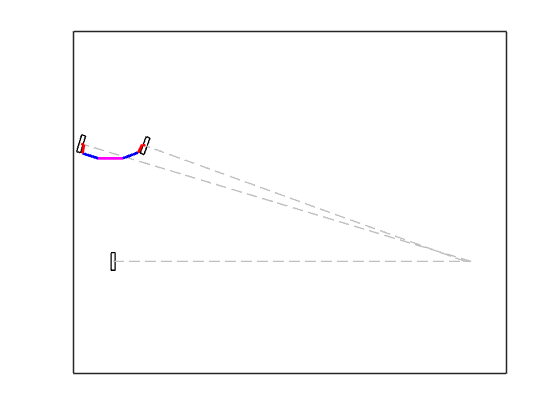

%% Generate Diagram %%

[whl_angle, tr_angle, rnp_end_pos] = solve_linkage('right', rack_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_pos);
[whl_angleL, tr_angleL, rnp_end_posL] = solve_linkage('left', rack_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_posL);

% Ackermann lines
iczv = @(pos, angle) pos(1) + pos(2).*cotd(angle);

intR = iczv(kingpin_pos, -whl_angle);
intL = iczv(kingpin_posL, -whl_angleL);

% Diagram
figure(1); clf; hold on;
box on; xticks([]); yticks([]);
axis equal;

tire([0 0], 0);
pos = kingpin_pos + rot([kingpin2contact 0], whl_angle);
tire(pos, whl_angle);
pos = kingpin_posL - rot([kingpin2contact 0], whl_angleL);
tire(pos, whl_angleL);

if (abs(whl_angle) > 10^-10)
    plot([0, (-sign(whl_angle)*max(abs(intR), abs(intL)))], [0 0], '--', 'color', [.75 .75 .75]);
    plot([intR, kingpin_pos(1)], [0, kingpin_pos(2)], '--', 'color', [.75 .75 .75]);
    plot([intL, kingpin_posL(1)], [0, kingpin_posL(2)], '--', 'color', [.75 .75 .75]);
    fit = xlim;
    if (sum(abs(fit)) > 5*wheelbase)
        xlim([-1.5*trackwidth, 1.5*trackwidth]);
        ylim([-0.2*wheelbase, 1.2*wheelbase]);
    else
        xlim(1.1*fit);
    end
else
    ylim([-0.2*wheelbase, 1.2*wheelbase]);
end

draw({rnp_end_pos, -rnp_length}, 'm');
draw({rnp_end_pos, rot([tie_rod_length 0], tr_angle)}, 'b');
draw({kingpin_pos, rot([kingpin2contact 0], whl_angle)}, 'r');
draw({kingpin_pos, rot(-steering_arm_Ivec, whl_angle)}, 'r');
draw({rnp_end_posL, rot([-tie_rod_length 0], -tr_angleL)}, 'b');
draw({kingpin_posL, rot([-kingpin2contact 0], whl_angleL)}, 'r');
draw({kingpin_posL, rot(-[-steering_arm_Ivec(1) steering_arm_Ivec(2)], whl_angleL)}, 'r');


whl_angle

whl_angle =       -19.884


whl_angleL

whl_angleL =       -16.783


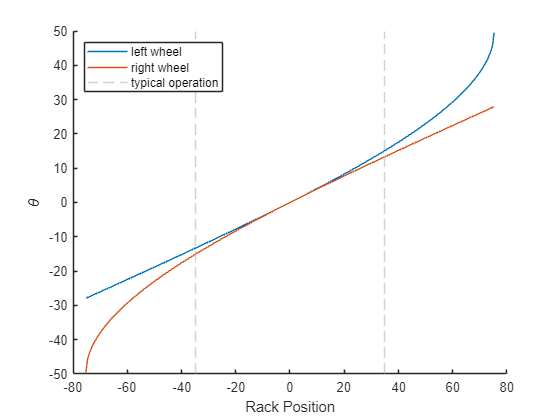

%% Ackermann Closeness %%

test_positions = linspace(max_movement_neg, max_movement, 256);
rightwhl = zeros(length(test_positions), 1);
leftwhl = zeros(length(test_positions), 1);
for i = 1:length(test_positions)
    test_pos = test_positions(i);
    [whl_angle, ~, ~] = solve_linkage('right', test_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_pos);
    [whl_angleL, ~, ~] = solve_linkage('left', test_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_posL);
    rightwhl(i) = whl_angle;
    leftwhl(i) = whl_angleL;
end

% Wheel angle
% add zoom btn %
figure(2); clf; hold on;

typical = interp1(leftwhl, test_positions, 15, 'linear', 'extrap');
p3 = xline(-typical, '--', 'color', [.75 .75 .75]); xline(typical, '--', 'color', [.75 .75 .75]);  % ~20m turn radius, typical for racetracks

p1 = plot(test_positions, leftwhl);
p2 = plot(test_positions, rightwhl);

xlabel('Rack Position'); ylabel('\theta');
legend([p1 p2 p3], {'left wheel', 'right wheel', 'typical operation'}, 'Location', 'northwest');

zoomlimitsX = xlim;
xlim(zoomlimitsX);

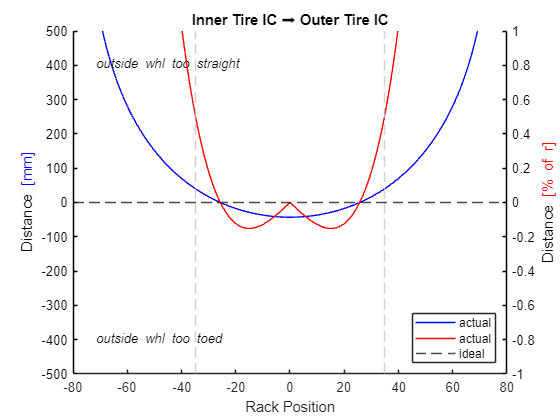


% Instant centres
figure(3); clf; hold on;
title('Inner Tire IC ➡ Outer Tire IC');
xlabel('Rack Position');
rightICZV = iczv(kingpin_pos, -rightwhl);
leftICZV = iczv(kingpin_posL, -leftwhl);

xlim(zoomlimitsX);
xline(-typical, '--', 'color', [.75 .75 .75]); xline(typical, '--', 'color', [.75 .75 .75]);
q3 = yline(0, '--k');


yyaxis right;
q2 = plot(test_positions, 200*(leftICZV-rightICZV)./abs(leftICZV+rightICZV), 'r');
ylim([-1 1]); %need to not be arb.
ylabel('Distance \color{red}[% of r]', 'interpreter', 'tex');
set(gca,'YColor','k');


yyaxis left;
q1 = plot(test_positions, leftICZV-rightICZV, 'b');
ylim([-500, 500]); %need to not be arb.
ylabel('Distance \color{blue}[mm]');

%ack_pct = (rightICZV-leftICZV)/wheelbase;  % this is not a standardized measure


legend([q1 q2 q3], {'actual', 'actual', 'ideal'}, 'Location', 'southeast');

zoomlimitsY = ylim;
text(0.9*zoomlimitsX(1), 0.8*zoomlimitsY(2), '\it{outside whl too straight}');
text(0.9*zoomlimitsX(1), 0.8*zoomlimitsY(1), '\it{outside whl too toed}');



% PLOT TURN RADIUS TMMR

% verifyack(trackwidth, wheelbase, norm(steering_arm_IvecL), tie_rod_length, atan(steering_arm_Ivec(1)/steering_arm_Ivec(2)), -atan(tie_rod_Ivec(2)/steering_arm_Ivec(1)));
% % equal at rack_pos = 0
% atand(tie_rod_Ivec(2)/tie_rod_Ivec(1))
% beta-phi

%% Functions %%

function result = inch(inches)
    result = inches * 25.4;
end

function result = rot(vec, angle)  % degrees
    rotM = [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
    if isrow(vec)
        vec = vec';
    end
    result = rotM * vec;
    result = result';
end

function [whl_angle, tr_angle, rnp_end_pos] = solve_linkage(side, rack_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_pos)
    coslaw = @(a, b, c) acosd((a^2 + b^2 - c^2) / (2*a*b));  % everything is in degrees

    if (strcmpi(side, 'right'))
        sgn = 1;
    elseif (strcmpi(side, 'left'))
        sgn = -1;
    else
        return
    end

    rnp_end_pos = [sgn*0.5*rnp_length + rack_pos, wheelbase - setback];
    rnp2kingpin_vec = kingpin_pos - rnp_end_pos;

    theta = coslaw(norm(rnp2kingpin_vec), norm(steering_arm_Ivec), tie_rod_length);             % connecting line to str arm
    alpha = atand(sgn*rnp2kingpin_vec(1)/rnp2kingpin_vec(2));                                   % connecting line to vert
    whl_angle = -sgn*(alpha - theta - atand(steering_arm_Ivec(1)/steering_arm_Ivec(2)));        % degrees from straight, pos is CW

    phi = coslaw(norm(rnp2kingpin_vec), tie_rod_length, norm(steering_arm_Ivec));               % connecting line to tie rod
    beta = atand(sgn*rnp2kingpin_vec(2)/rnp2kingpin_vec(1));                                    % connecting line to horz
    tr_angle = beta - phi;                                                                      % degrees from horz
    
    %disp(beta + alpha)
end

function tire(pos, angle)  % degrees
    t = 35; r = 150;
    rotM = [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
    offset = rotM*[t, -t, -t, t, t;
                  r, r, -r, -r, r];
    plot(pos(1) + offset(1,:), pos(2) + offset(2,:), 'k');
end

function draw(coords, style)  % coords = {[A, B]; C; C; C; C} where C can be 1x1 or 2x1 (optional y val)
    x = coords{1}(1); y = coords{1}(2);
    for i = 2:length(coords)
        x_old = x; y_old = y;
        x = coords{i}(1) + x_old;
        if (length(coords{i}) >= 2); y = coords{i}(2) + y_old; else; y = y_old; end  % same as above but handles empty y
        plot([x_old, x], [y_old, y], style, 'LineWidth', 2);
    end
end




function verifyack(w, L, a, b, theta, phi)
disp(theta)
disp(phi)
disp(theta-phi)
    disp(tan(theta-phi))
    fprintf('w/L = %f\n', w/L);
    RS = tan(theta-phi)*( 1+a/b*sin(theta)^2*sec(theta)^3*csc(theta-phi) );
    fprintf('RS = %f\n', RS);
end